%%%%%%%%%%%%%%%%%%%%%%%%%%%%％％％％％％％%%%%%
% ch 50直下のピクセルにフォーカスをかける．
% フォーカス深度を１グリッドずつ変化させて，開口合成受信データを生成する．
% F値を固定する．最近接距離をいくつに設定する？
% x-axis: 20 mmのときに全素子を使うという前提を設ける．
% 対象にする媒質データ：case26を用いる．
% IMCL割合を0 %に固定する．
% kgrid.x_vec が0となるのは251番目の要素．
% グリッド幅が0.1 mm
% 素子間ピッチが0.4 mm
% よって，最近接深度(最近接距離は0.4 mm)
% 深度ごとの細かい素子割当は，floor()を用いる．
% 整相加算の際に参照する音速を1580 m/sとする．
% 整相加算の前に参照点と受信chごとの振幅(ヒルベルト変換後絶対値)最大値との距離の
% 合計を評価関数として媒質の均質性を評価することも同時に行う．
% update:rf-dataの配列サイズが大きくなってきたので，変数区分を細分化して各変数の呼び出し速度を上げる．[2018/11/05]
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear;
load("H:/data/kwave/config/t_pos_2board.mat");
load("H:/data/kwave/medium/2018_11_07_layer_medium/reference.mat")
pathname = sprintf('H:/data/kwave/result/2018_11_07_layer_medium/Layer_medium_boundary_7.9mm_ IMCL%d%%',1);
cd(pathname);
load('rfdata.mat');
load('kgrid.mat');
% load("H:/data/kwave/result/2018_10_21_point_medium/point_mudium5MHz/rfdata.mat");
% load("H:/data/kwave/result/2018_10_21_point_medium/point_mudium5MHz/medium.mat");
% load("H:/data/kwave/result/2018_10_21_point_medium/point_mudium5MHz/kgrid.mat");

% 初期設定
v_fat = 1450;%[m/s]
v_muscle = 1580;%[m/s]
rate_IMCL = linspace(1,20,20);
v_reference = zeros(1,length(rate_IMCL));
t_facing_distance = 0.04;%[m]
[~,num_receiver,num_transmitter] = size(rfdata);
num_echo_receiver = num_transmitter;
num_rate_IMCL = length(rate_IMCL);
num_medium  = num_rate_IMCL;
reference_point = zeros(1,num_echo_receiver);
reference_point_lowerlimit = zeros(1,num_echo_receiver);%均質性評価のためのRFデータマスキングに使う
reference_point_upperlimit = zeros(1,num_echo_receiver);%均質性評価のためのRFデータマスキングに使う
point_maxAmp_in_mask = zeros(1,num_echo_receiver);%マスク処理後のRFデータで振幅最大のサンプル点情報
distance_from_focal_point_all = zeros(1,num_echo_receiver);
% focal_signal_total = zeros(length(rate_IMCL),num_depth);
% focal_signal_total2 = zeros(length(rate_IMCL),num_depth);
focal_amp = zeros(1,num_echo_receiver);
% focal_phase = zeros(length(rate_IMCL),num_depth,num_echo_receiver);
homogeneity_percel = zeros(num_rate_IMCL,num_echo_receiver);
homogeneity_total = zeros(num_rate_IMCL,num_medium);


num_depth = (t_pos(2,1)-t_pos(2,101))/kgrid.dx - 3;%'3'とあるのは，最近接距離が0.4 mmであることを考慮している．
focal_depth = zeros(1,num_depth);
focal_point = zeros(2,num_depth);
for ii = 1:num_depth
    focal_depth(1,ii) = (ii+3)*kgrid.dx;
    focal_point(2,ii) = t_pos(2,1)-focal_depth(1,ii);
    focal_point(1,ii) = 0;
end


for ll = 1:20
    pathname = sprintf('H:/data/kwave/result/2018_11_07_layer_medium/Layer_medium_boundary_7.9mm_ IMCL%d%%',ll);
    cd(pathname);
    load('rfdata.mat');
    load('kgrid.mat');
    [num_sample,~,~] = size(rfdata);
    focused_rfdata = zeros(num_sample,num_echo_receiver);
    focused_rfdata_masked = zeros(num_sample,num_echo_receiver);
    focused_rfdata_amp = zeros(num_sample,num_echo_receiver);
    focused_rfdata_amp_masked = zeros(num_sample,num_echo_receiver);
    for kk = 1:num_rate_IMCL
        v_reference(1,kk) = v_muscle*(1-rate_IMCL(1,kk)/100) + v_fat*(rate_IMCL(1,kk)/100);
        for ii = k
            target_element = find((-focal_depth(1,ii)/2<=t_pos(1,1:100)&(t_pos(1,1:100)<=focal_depth(1,ii)/2)));
            distance_from_focal_point = zeros(1,length(target_element));
            %受信用の参照点算出
            for jj = 1:num_echo_receiver
                distance_from_focal_point_all(1,jj) = norm(t_pos(:,jj) - focal_point(:,ii));
                delay_time_all = round(((distance_from_focal_point_all - focal_depth(1,ii))/v_reference(1,kk))/kgrid.dt);%[sample]
                reference_point(1,jj) = round(delay_time_all(1,jj)+1+(2*focal_depth(1,ii)/v_reference(1,kk))/kgrid.dt+25);
                %25はfocal_amplitudeを最大にするオフセット．
                reference_point_lowerlimit(1,jj) ...
                    = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_muscle)+1+(2*focal_depth(1,ii)/v_muscle)/kgrid.dt+25-1);
                reference_point_upperlimit(1,jj) ...
                    = round(delay_time_all(1,jj)*(v_reference(1,kk)/v_fat)+1+(2*focal_depth(1,ii)/v_fat)/kgrid.dt+25);
                %どんなに遅延しても早く到達してもこの範囲内に焦点位置からのエコーパルスが入っているであろう上限・下限
            end
            %送信ビームフォーミング（共通）
            for jj = 1:length(target_element)
                distance_from_focal_point(1,jj) = distance_from_focal_point_all(1,target_element(jj));
                % 遅延処理
                delay_time = delay_time_all(1,target_element(jj));%[sample]
                read_range_rfdata = length(delay_time+1:num_sample);
                focused_rfdata(1:read_range_rfdata,:) = focused_rfdata(1:read_range_rfdata,:)...
                    +  rfdata(delay_time+1:num_sample,1:100,target_element(jj));%整相加算
            end
            hilb_rfdata = hilbert(focused_rfdata);
            focused_rfdata_amp = abs(hilb_rfdata);
            %         focused_rfdata_phase(:,:,ii) = atan(imag(hilb_rfdata)./real(hilb_rfdata));
            focused_rfdata_amp_masked = focused_rfdata_amp;
            focused_rfdata_masked = focused_rfdata;
            %RFデータマスキング（均質性評価のため）
            for jj = 1:num_echo_receiver
                focused_rfdata_amp_masked(1:reference_point_lowerlimit(1,jj),jj) = 0;
                focused_rfdata_amp_masked(reference_point_upperlimit(1,jj):end,jj) = 0;
                focused_rfdata_masked(1:reference_point_lowerlimit(1,jj),jj) = 0;
                focused_rfdata_masked(reference_point_upperlimit(1,jj):end,jj) = 0;
            end
            [~,point_maxAmp_in_mask] = max(focused_rfdata_amp_masked,[],1);
            for jj = 1:length(target_element)
                %受信ビームフォーミング（整相加算のため）
                %                 focal_signal_total(kk,ii) = focal_signal_total(kk,ii)+ ...
                %                     focused_rfdata_amp(reference_point(target_element(1,jj),ii,kk),target_element(1,jj),ii,kk)/length(target_element);
                %                 focal_signal_total2(kk,ii) = focal_signal_total2(kk,ii)+ ...
                %                     focused_rfdata(reference_point(target_element(1,jj),ii,kk),target_element(1,jj),ii,kk)/length(target_element);
                %                 focal_amp(kk,ii,target_element(jj)) = ...
                %                     focused_rfdata_amp(reference_point(target_element(1,jj),ii,kk),target_element(1,jj),ii,kk)/length(target_element);
                %均質性評価指標
                homogeneity_percel(kk,jj) = abs(point_maxAmp_in_mask(1,target_element(jj)) - reference_point(1,target_element(jj)));
            end
            homogeneity_total(kk,ll) = sum(homogeneity_percel(kk,:))/length(target_element);
        end
    end
end

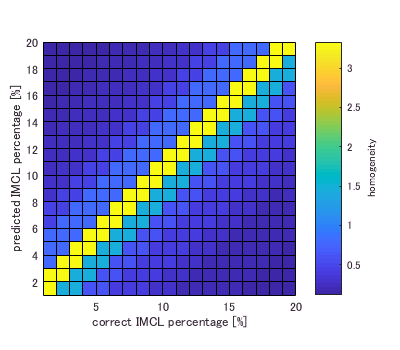

figure;

pcolor(homogeneity);
colorbar;
c = colorbar;
c.Label.String = 'homogeneity';
axis equal
axis tight
xlabel('correct IMCL percentage [%]');
ylabel('predicted IMCL percentage [%]')
exportfig('H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\predeiction_vs_correct_IMCL_percentage_pcolor_eng','png',[400,350]);

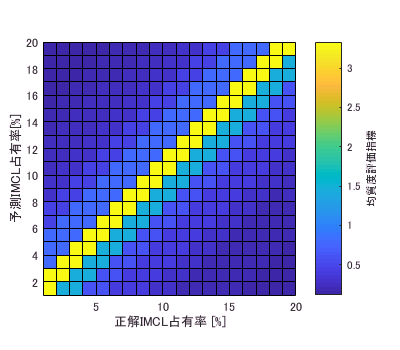

figure;
pcolor(homogeneity);
colorbar;
c = colorbar;
c.Label.String = '均質度評価指標';
axis equal
axis tight
xlabel('正解IMCL占有率 [%]');
ylabel('予測IMCL占有率[%]')
exportfig('H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\predeiction_vs_correct_IMCL_percentage_pcolor','png',[400,350]);